# **Lab 4: Stereo Visual Odometry**

**Visual Odometry(VO)** is the process of estimating the 6 DOF motion of a vehicle from one or multiple camera video input. Here, we have a camera (or array of cameras) rigidly attached to a moving object, and we want to estimate the position and rotation using the video stream. When we use one camera the process is called **Monocular Visual Odometry; **whereas, with a two camera system it is referred as **Stereo Visual Odometry.**

#### **Why use stereo or monocular?**

The advantage of stereo is that you can estimate the trajectory including its scale, while in monocular you can only estimate the shape of the trajectory, but not its true scale. So, in monocular VO, you can only say that you moved some arbitrary units in x, y, and z. On the other hand, stereo VO tends to be more robust, but in cases where the distance to the objects is too high the stereo case degenerates to the monocular case.

## Framework

There are plenty of approaches to implement Stereo VO. The simple algorithm that we are going to implement follows the next schematic:

- **System initialization:** The first frame of the video sequence is obtained and the system, camera parameters, and intial position is initialized.

- **Receiving new data:** A new stereo pair set is received into the system.

- **Feature detection and extraction:** Detect the features on the left and right images an perform the extraction of the descriptors.

- **Matching:** The matching is performed in a circular way between two set of consecutive frames.

- **Triangulation of 3D points:** Stereo triangulation is used to obtain the 3D points of the frame at a time t-1.

- **Computing R and T matrices:** The 3D points are reprojected into the current image, and by iteratively solving the minimum reprojection error, the rotation R and translation T matrices are computed. These matrices represents the incremental movement performed by the system from t-1 to t.

- Iterate until all frames are processed.

## **Download and Explore the Input Stereo Image Sequence**

The data used in this example are from the [UTIAS Long-Term Localization and Mapping Dataset](http://asrl.utias.utoronto.ca/datasets/2020-vtr-dataset/) provided by University of Toronto Institute for Aerospace Studies. 

You can download the data to a temporary directory using a web browser or run the following code to get it from an FTP server (this is usually slow). If you already have your data downloaded as a zip file, then set the *getFileFromFTP* variable to false, create a temporary folder, extract your zip file there, and then set the variable *dataFolder* to that folder that contains the zip file.

% Cleaning the work environment
clc;
clear;

getFileFromFTP = false;

if ~getFileFromFTP
    % this is the folder where the zip file should extracted to. Be sure to end the string with the folder separator (\ or /) 
    dataFolder = "C:\Users\solom\Desktop\Multiview-Geometry\temp_for_lab4\temp_for_lab4\"; 
else
    % Loading data from FTP site
    ftpObj       = ftp('asrl3.utias.utoronto.ca');
    tempFolder   = fullfile(tempdir)
    ftpFolder   = '2020-vtr-dataset/UTIAS-In-The-Dark/';
    ftpFileName = 'run_000004.zip';
    dataFolder   = [tempFolder, ftpFolder];
    zipFileName  = [dataFolder, ftpFileName];
    folderExists = exist(dataFolder, 'dir');

    % Create a folder in a temporary directory to save the downloaded file
    if ~folderExists
        mkdir(dataFolder);
        disp(['Downloading ' ftpFileName '  (818 MB). This download can take a few minutes.']);
        mget(ftpObj,['/' ftpFolder ftpFileName], tempFolder);

        % Extract contents of the downloaded file
        disp(['Extracting ' zipFileName '  ...'])
        unzip(zipFileName, dataFolder);
    end
end


We use two [`imageDatastore`](https://www.mathworks.com/help/matlab/ref/matlab.io.datastore.imagedatastore.html) objects to store the stereo images.

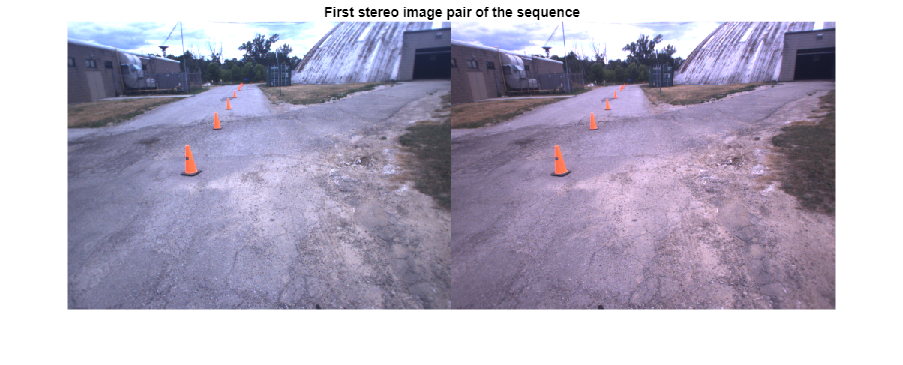

imgFolderLeft  = [dataFolder,'images/left/'];
imgFolderRight = [dataFolder,'images/right/'];
imdsLeft       = imageDatastore(imgFolderLeft);
imdsRight      = imageDatastore(imgFolderRight);

% Inspect the first pair of images
currFrameIdx   = 1;
currILeft      = readimage(imdsLeft, currFrameIdx);
currIRight     = readimage(imdsRight, currFrameIdx);
imshowpair(currILeft, currIRight, 'montage');
title('First stereo image pair of the sequence');

## |Set the camera parameters

Next we initialize our camera system. This consist of two cameras that are mounted on the same rig and displaced by some distance (baseline). The stereo system needs to consider the intrinsic matrices of the cameras $K_1$, $K_2$ , which are equal in this case. Also, the extrinsic parameters of camera2 (right camera) is defined by the baseline and no rotation in the coordinate system. Remeber that:

$K=\left\lbrack \begin{array}{ccc}
f_u  & 0 & u_0 \\
0 & f_v  & v_o \\
0 & 0 & 1
\end{array}\right\rbrack$ and $P=K\;\left\lbrack \begin{array}{cc}
R & t
\end{array}\right\rbrack$

To do this you can make use of matlab structures such as [cameraPameters](https://es.mathworks.com/help/vision/ref/cameraparameters.html) and [StereoParameters](https://es.mathworks.com/help/vision/ref/stereoparameters.html).

% Load the initial camera pose. The initial camera pose is derived based 
% on the transformation between the camera and the vehicle:
% http://asrl.utias.utoronto.ca/datasets/2020-vtr-dataset/text_files/transform_camera_vehicle.txt 
initialPoseRotation = [7.963270829459690e-04, -0.999999682931538, 1.034228258589565e-12; -0.330471987613750, -2.631638783086032e-04, -0.943815763879472; 0.943815464625260, 7.515860537466446e-04, -0.330472092396028];
initialPoseTranslation = [0.159, 0.119, 1.528];
initialPose = rigid3d(initialPoseRotation,initialPoseTranslation); % create a rigid3d object with the initial camera pose

% Create a stereoParameters object to store the stereo camera parameters.
% The intrinsics for the dataset can be found at the following page:
% http://asrl.utias.utoronto.ca/datasets/2020-vtr-dataset/text_files/camera_parameters.txt
focalLength     = [387.777 387.777];     % specified in pixels
principalPoint  = [257.446 197.718];     % specified in pixels [x, y]
baseline        = 0.239965;              % specified in meters
intrinsicMatrix = [focalLength(1), 0, 0; 0, focalLength(2), 0; principalPoint(1), principalPoint(2), 1]; % Note that matlab uses the K matrix as the transpose of what the noormal convention...
imageSize       = size(currILeft,[1:2]); % in pixels [mrows, ncols]
cameraParam     = cameraParameters('IntrinsicMatrix', intrinsicMatrix, 'ImageSize', imageSize);
intrinsics      = cameraParam.Intrinsics;
stereoParams    = stereoParameters(cameraParam, cameraParam, eye(3), [-baseline, 0 0]);

## Processing a new incoming frame

Before continuing with the process, we must perform a number of preprocessing steps. The first is to undistort the images, which is a process that compensates for lens distortion. Then, a rectification step is needed to completely aligned the image from the left camera with the right camera.

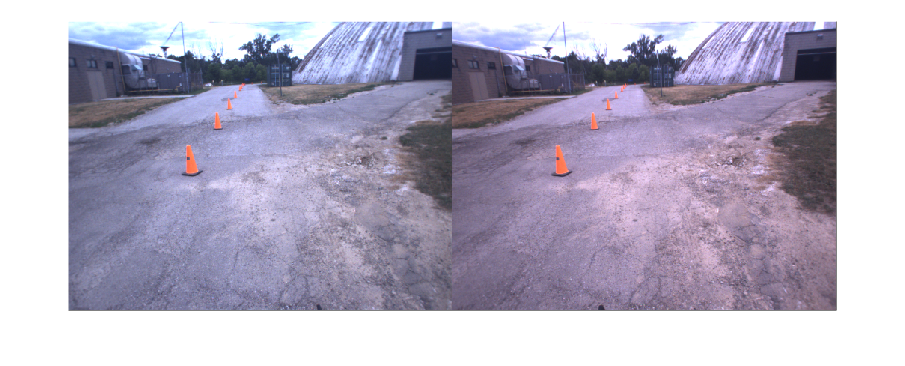

% In this example, the images are already undistorted. In a general
% workflow, uncomment the following code to undistort the images.
currILeft  = undistortImage(currILeft, intrinsics);
currIRight = undistortImage(currIRight, intrinsics);

% Rectify the stereo images
[currILeft, currIRight] = rectifyStereoImages(currILeft, currIRight, stereoParams, 'OutputView','full');
imshowpair(currILeft, currIRight, 'montage');

## Feature extraction

After the pre-processing step of the images, we need to extract the features that we will use later to compare which points on each image correspond to the same point. To do this you can use any feature detector that you prefer. Information of different feature detectors can be found [here](https://www.analyticsvidhya.com/blog/2021/06/feature-detection-description-and-matching-of-images-using-opencv/). Each feature detector and extraction algorithm works on the entire image, but this can give you results in which most features would be concentrated in certain rich regions while other regions would not have any representation. This is not good for a VO system, since it relies on the assumption of a static scene, and to find it we must look into all the image. 

In order to tackle this, one approach that we can explore is called **Bucketing**, which basically consists on dividing the image into grids and extract features from each of this grids, thus maintaining a more uniform distribution of features.

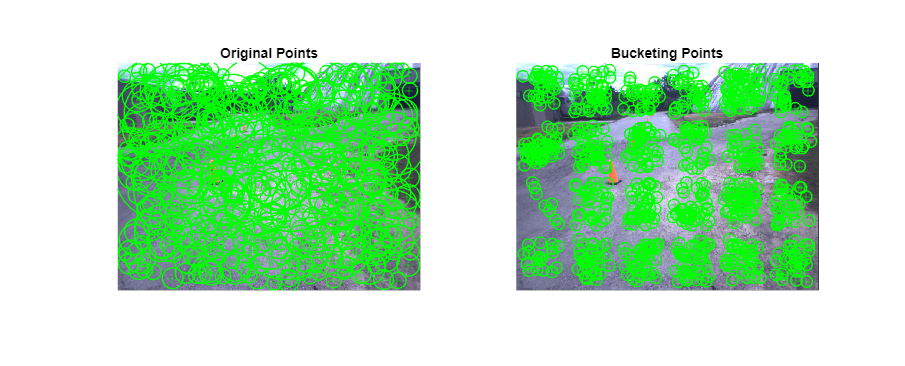

% Setting extractor parameters
numPoints = 500; % Total points to extract uniformly
MetricThreshold = 50; % A lower value extracts more feature
ScaleLevels = 6;

% Detect Features in the left image
[currFeaturesLeft_n, currPointsLeft_n] = DetectandExtractFeatures(currILeft,MetricThreshold,ScaleLevels,numPoints);

% Detect features by bucketing
h_divs = 4;
w_divs = 6;
[currFeaturesLeft, currPointsLeft] = BucketFeaturesExtraction(currILeft,MetricThreshold,ScaleLevels,numPoints,w_divs,h_divs);

% Detect Features in the right image
[currFeaturesRight, currPointsRight] = BucketFeaturesExtraction(currIRight,MetricThreshold,ScaleLevels,numPoints,w_divs,h_divs);

% Visualizing the results of each technique in the left image
subplot(1,2,1)
imshow(currILeft); hold on; plot(currPointsLeft_n); hold off;
title('Original Points')

subplot(1,2,2)
imshow(currILeft); hold on; plot(currPointsLeft); hold off
title('Bucketing Points')

## Circular matching

The matching technique that we are going to explore for our system is called **Circular matching. **Basically, It consists in taking a feature ($P_1$) from the left camera frame at time $t-1$ and compare it against al features in the right image at time $t-1$. The best match of this process will be our feature $P_2$ and we will match it with the correspoding right image at time $t$. This process is repeated until we close the cycle, and if $P_5 =P_1$ then we consider it as a good match.

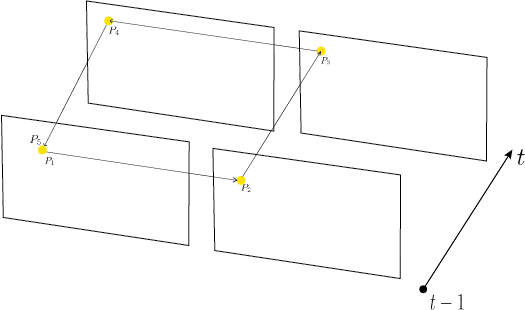

You can now implement this algorithm and show some results of the points matched in image left $t-1$ and image let at $t$ after this process.

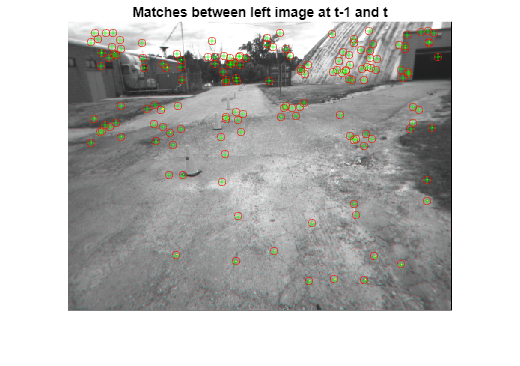

%% Getting a new stereo pair
% Saving previous frame data
lastILeft = currILeft;
lastIRigt = currIRight;
prevPointsLeft = currPointsLeft;
prevDescriptorsLeft = currFeaturesLeft;
prevPointsRight = currPointsRight;
prevDescriptorsRight = currFeaturesRight;

% Reading the new frame
currFrameIdx   = 2;
currILeft      = readimage(imdsLeft, currFrameIdx);
currIRight     = readimage(imdsRight, currFrameIdx);

% Undistort the images
%currILeft  = undistortImage(currILeft, intrinsics);
%currIRight = undistortImage(currIRight, intrinsics);
% Rectify the stereo images
[currILeft, currIRight] = rectifyStereoImages(currILeft, currIRight, stereoParams, 'OutputView','full');

% Computing features for the current frame
% Left image
[currFeaturesLeft, currPointsLeft] = BucketFeaturesExtraction(currILeft,MetricThreshold,ScaleLevels,numPoints,w_divs,h_divs);
% Right image
[currFeaturesRight, currPointsRight] = BucketFeaturesExtraction(currIRight,MetricThreshold,ScaleLevels,numPoints,w_divs,h_divs);


% Iterate over all keypoint observations of image_left at t-1
% A successful match is only declared when, after the cycle, the keypoint
% in the left image at t-1 is tracked and match over all images.
matches_l1 = [];
matches_r1 = [];
matches_l2 = [];
matches_r2 = [];

for kpt_left1 = 1:size(prevDescriptorsLeft,1)
    % Matching first feature in left t-1 with right t-1
    idx_pairs_l1_r1 = matchFeatures(prevDescriptorsLeft(kpt_left1,:),prevDescriptorsRight);
    if isempty(idx_pairs_l1_r1)
        continue;
    end

    % Matching found feature in right t-1 with features in right t
    idx_pairs_r1_r2 = matchFeatures(prevDescriptorsRight(idx_pairs_l1_r1(2),:),currFeaturesRight);
    if isempty(idx_pairs_r1_r2)
        continue;
    end

    % Matching found feature in right t with features in left t
    idx_pairs_r2_l2 = matchFeatures(currFeaturesRight(idx_pairs_r1_r2(2),:),currFeaturesLeft);
    if isempty(idx_pairs_r2_l2)
        continue;
    end

    % Matching found feature in left t with features in left t-1
    % closing the cycle
    idx_pairs_l2_l1 = matchFeatures(currFeaturesLeft(idx_pairs_r2_l2(2),:),prevDescriptorsLeft);
    if isempty(idx_pairs_l2_l1)
        continue;
    end

    % If the circular matching has been successful then accept the feature
    % as a match
    if (kpt_left1==idx_pairs_l2_l1(2))
        % Retrieve the coordinates of matched features
        matched_pt_l1 = prevPointsLeft(kpt_left1);
        matched_pt_l2 = currPointsLeft(idx_pairs_r2_l2(2));
        matched_pt_r1 = prevPointsRight(idx_pairs_l1_r1(2));
        matched_pt_r2 = currPointsRight(idx_pairs_r1_r2(2));

        matches_l1 = [matches_l1;kpt_left1];
        matches_r1 = [matches_r1;idx_pairs_l1_r1(2)];
        matches_l2 = [matches_l2;idx_pairs_r2_l2(2)];
        matches_r2 = [matches_r2;idx_pairs_r1_r2(2)];
    end
end

pts_matches_l1 = prevPointsLeft(matches_l1);
pts_matches_r1 = prevPointsRight(matches_r1);
pts_matches_l2 = currPointsLeft(matches_l2);
pts_matches_r2 = currPointsRight(matches_r2);

figure; showMatchedFeatures(lastILeft,currILeft,pts_matches_l1,pts_matches_l2);
title('Matches between left image at t-1 and t')

## **Comparing two methods to estimate stereo motion**

We will now compare two distinct approaches for performing stereo registration and we will compare them in terms of uncertainty of the results that the two aproaches provide. 

Both approaches take, as input, two pairs of stereo images acquired with the same stereo camera. It further assumes that we are able to find correct matches between all four images, i.e we have a set of points in one image where we know their correspondences in the other 3 images. We call this points as 'circular' matches.

The first approach, called "3D to 3D", consists in 

- Creating two 3D point clouds, one for each stereo pair, 

- Aligning the point clouds using a rigid 3D transformation model

- Extracting the translation and rotation from the rigid 3D transformation model

The second approach, called "2D to 3D", consists in

- Creating just one 3D point cloud, from the first stereo pair

- Select the 2D points from one of the cameras of the second stereo pair

- Solve the *Perspective-n-Point *(*P3P*) problem using these 2D points and the 3D point of the first stereo pair.

The Perspective-n-Point problem concerns the estimation of the pose of a calibrated camera given a set of *n* 3D points in the world and their corresponding 2D projections in the image. You can think of this problem as a simplified case of the camera calibration problem where we are only interested in finding the **R, t** elements of the camera projection matrix instead of the full projection matrix **P**. You can quickly read more information on this method [here](https://en.wikipedia.org/wiki/Perspective-n-Point).

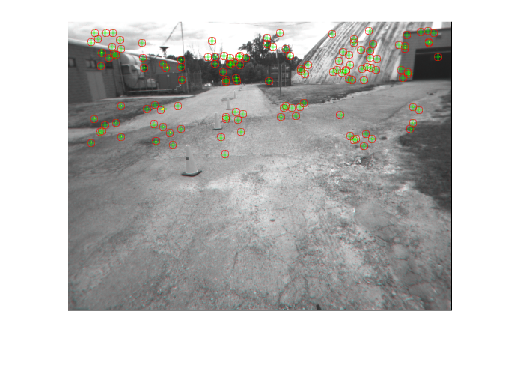

% Method 3D to 3D
% Get all matches for all images. These are filtered matches using the function below that implements robust estimation 
inlierIdx = getInliersIdx(pts_matches_l1,pts_matches_r1,pts_matches_l2,stereoParams);
pts_matches_l1_uv = prevPointsLeft(matches_l1(inlierIdx)).Location;
pts_matches_r1_uv = prevPointsRight(matches_r1(inlierIdx)).Location;
pts_matches_l2_uv = currPointsLeft(matches_l2(inlierIdx)).Location;
pts_matches_r2_uv = currPointsRight(matches_r2(inlierIdx)).Location;

figure; showMatchedFeatures(lastILeft,currILeft,pts_matches_l1_uv,pts_matches_l2_uv);

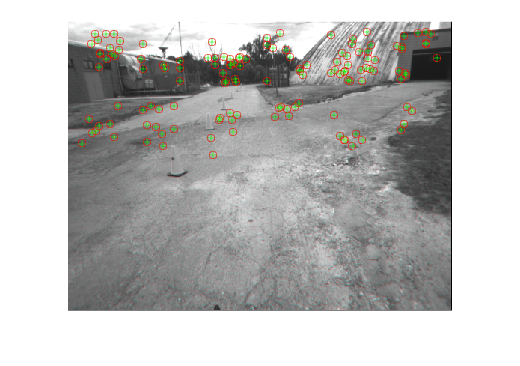

figure; showMatchedFeatures(lastIRigt,currIRight,pts_matches_r1_uv,pts_matches_r2_uv);

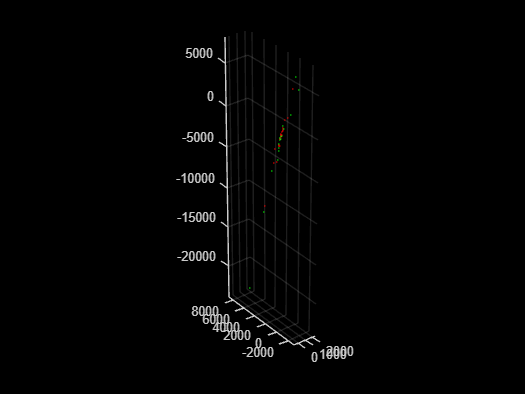


% Triangulation of 3D points at time t-1
points3D_t1 = triangulate(pts_matches_l1_uv,pts_matches_r1_uv,stereoParams);

% Triangulation of 3D points at time t
points3D_t2 = triangulate(pts_matches_l2_uv,pts_matches_r2_uv,stereoParams);

% Show the two point clouds, before alignment
figure; pcshow(points3D_t1,[1 0 0]); hold on; pcshow(points3D_t2,[0 1 0]);

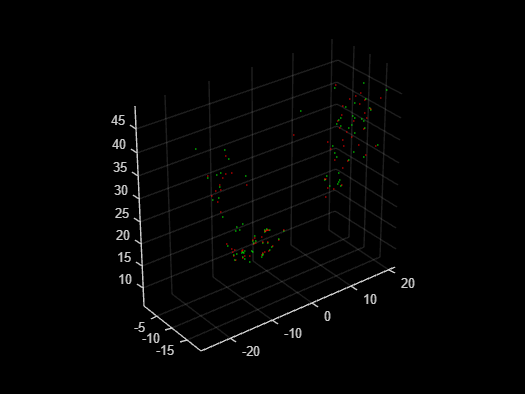


% Select only points that are in a section of the 3D space 
zmin = 0.5; % all points must be farther than this, in meters 
zmax = 50;  % all points must be closer than this, in meters 
[points3D_t1_valid,points3D_t2_valid] = select_based_on_z_distance(points3D_t1,points3D_t2,zmin,zmax);

% Show the two point clouds, before alignment, but after removing areas that are not valid
figure; pcshow(points3D_t1_valid,[1 0 0]); hold on; pcshow(points3D_t2_valid,[0 1 0]);


% Align using a rigid 3D transformation model
estimatedTform = estimateGeometricTransform3D(points3D_t2_valid, points3D_t1_valid,'rigid');

disp(['The result of 3D to 3D (translation) is ' num2str(estimatedTform.Translation)]);

The result of 3D to 3D (translation) is -0.058262     0.01922   -0.081291


% Method 2D to 3D

% Triangulation of 3D points at time t-1
points3D_t1 = triangulate(pts_matches_l1_uv,pts_matches_r1_uv,stereoParams);

[R,t] = estimateWorldCameraPose(pts_matches_l2_uv,points3D_t1,intrinsics,'MaxReprojectionError', 10);

disp(['The result of 2D to 3D (translation) is ' num2str(t)]);

The result of 2D to 3D (translation) is -0.012069   -0.016013    0.033194


## **Performing sensitivity analysis using Monte Carlo**

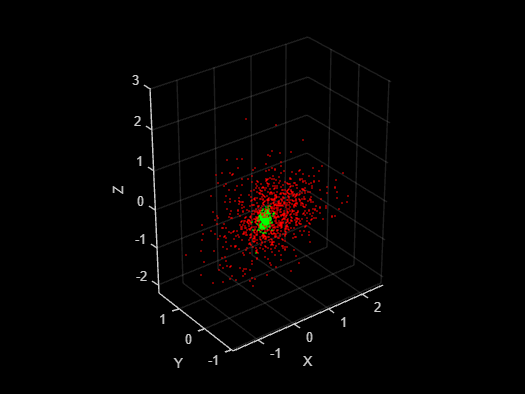


% Do Monte-Carlo sensitivity test for method 3D to 3D
noiseSTD = 0.1; % st dev of noise in pixels
numRuns = 1000; % number of runs

% This is a call to the function that you have to create.
% There is an empty function at the end of the live script for you to fill in 
[translationStack_3D3D] = mvg_montecarlo_3d_to_3d_reg(pts_matches_l1_uv,pts_matches_r1_uv,pts_matches_l2_uv,pts_matches_r2_uv,stereoParams,noiseSTD,numRuns);

translationMean = mean(translationStack_3D3D);
translationCov = cov(translationStack_3D3D);


% This is a call to the function that you have to create.
% There is an empty function at the end of the live script for you to fill in 
[translationStack_2D3D] = mvg_montecarlo_2d_to_3d_reg(pts_matches_l1_uv,pts_matches_r1_uv,pts_matches_l2_uv,pts_matches_r2_uv,stereoParams,noiseSTD,numRuns);


% This are just two alternative ways of showing the same data
figure;
pcshow(translationStack_3D3D,[1 0 0],'MarkerSize',15);
hold on;
pcshow(translationStack_2D3D,[0 1 0],'MarkerSize',15);
xlabel('X'); ylabel('Y'); zlabel('Z');

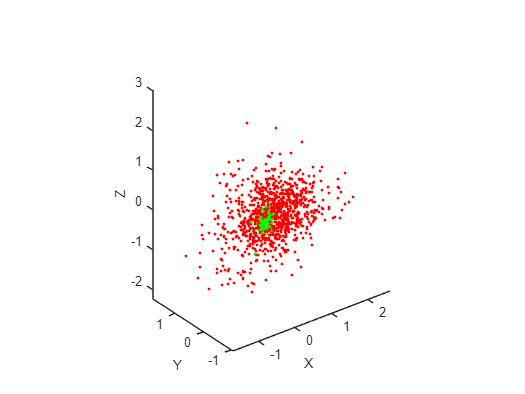


figure;
plot3(translationStack_3D3D(:,1),translationStack_3D3D(:,2),translationStack_3D3D(:,3),'r.','MarkerSize',6);
hold on;
plot3(translationStack_2D3D(:,1),translationStack_2D3D(:,2),translationStack_2D3D(:,3),'g.','MarkerSize',6);
xlabel('X'); ylabel('Y'); zlabel('Z');
axis equal;

## **Processing the complete sequence of stereo pairs**

Repeat the process for all the images in the dataset and plot the trajectory resulting from the acquisition of the pose.

R_prev = initialPoseRotation;
t_prev = [initialPoseTranslation]';
t_hist = [t_prev'];
step_frames = 2;

lastFrameToProcess = size(imdsLeft.Files,1);

for currFrameIdx = 2:step_frames:lastFrameToProcess
    % Reading the new frame
    disp(['Reading img ' num2str(currFrameIdx)]);
    currILeft      = readimage(imdsLeft, currFrameIdx);
    currIRight     = readimage(imdsRight, currFrameIdx);
    
    % Undistort the images
    %currILeft  = undistortImage(currILeft, intrinsics);
    %currIRight = undistortImage(currIRight, intrinsics);
    % Rectify the stereo images
    [currILeft, currIRight] = rectifyStereoImages(currILeft, currIRight, stereoParams, 'OutputView','full');
    
    % Computing features for the current frame
    % Left image
    [currFeaturesLeft, currPointsLeft] = BucketFeaturesExtraction(currILeft,MetricThreshold,ScaleLevels,numPoints,w_divs,h_divs);
    % Right image
    [currFeaturesRight, currPointsRight] = BucketFeaturesExtraction(currIRight,MetricThreshold,ScaleLevels,numPoints,w_divs,h_divs);

    % Getting valid matches
    matched_pts_idxs = CircularMatching(prevPointsLeft,prevPointsRight,currPointsLeft,currPointsRight,...
        prevDescriptorsLeft,prevDescriptorsRight,currFeaturesLeft,currFeaturesRight);

    pts_matches_l1 = prevPointsLeft(matched_pts_idxs.left1);
    pts_matches_r1 = prevPointsRight(matched_pts_idxs.right1);
    pts_matches_l2 = currPointsLeft(matched_pts_idxs.left2);
    pts_matches_r2 = currPointsRight(matched_pts_idxs.right2);

    % Triangulation of 3D points at t-1
    %points3D_t1 = triangulate(pts_matches_l1,pts_matches_r1,stereoParams);
    [points3D_t1,~,valid3D_t1] = triangulate(pts_matches_l1,pts_matches_r1,stereoParams);
    points3D_t1 = points3D_t1(valid3D_t1,:);

    %points3D_t2 = triangulate(pts_matches_l2,pts_matches_r2,stereoParams);
    [points3D_t2,~,valid3D_t2] = triangulate(pts_matches_l2,pts_matches_r2,stereoParams);
    points3D_t2 = points3D_t2(valid3D_t2,:);

    ptCloud_t1 = pointCloud(points3D_t1);
    ptCloud_t2 = pointCloud(points3D_t2);
    
    %%  motion estimation %%
    pts_matches_l2_valid_locations = pts_matches_l2(valid3D_t1).Location; % Get valid locations, i.e. 2D coordinates of valid points
    [R,t] = estimateWorldCameraPose(pts_matches_l2_valid_locations,points3D_t1,intrinsics,'Confidence', 95, 'MaxReprojectionError', 2, 'MaxNumTrials', 1e4);
    w_T_c = [R' t';0 0 0 1];


    t_i = inv(w_T_c)*[t_prev;1];
    t_prev = t_i(1:3);
    t_hist = [t_hist;t_i(1:3)'];

    % Saving previous frame data
    lastILeft = currILeft;
    lastIRigt = currIRight;
    prevPointsLeft = currPointsLeft;
    prevDescriptorsLeft = currFeaturesLeft;
    prevPointsRight = currPointsRight;
    prevDescriptorsRight = currFeaturesRight;
end

Reading img 2
Reading img 4
Reading img 6
Reading img 8
Reading img 10
Reading img 12
Reading img 14
Reading img 16
Reading img 18
Reading img 20
Reading img 22
Reading img 24
Reading img 26
Reading img 28
Reading img 30
Reading img 32
Reading img 34
Reading img 36
Reading img 38
Reading img 40
Reading img 42
Reading img 44
Reading img 46
Reading img 48
Reading img 50
Reading img 52
Reading img 54
Reading img 56
Reading img 58
Reading img 60
Reading img 62
Reading img 64
Reading img 66
Reading img 68
Reading img 70
Reading img 72
Reading img 74
Reading img 76
Reading img 78
Reading img 80
Reading img 82
Reading img 84
Reading img 86
Reading img 88
Reading img 90
Reading img 92
Reading img 94
Reading img 96
Reading img 98
Reading img 100
Reading img 102
Reading img 104
Reading img 106
Reading img 108
Reading img 110
Reading img 112
Reading img 114
Reading img 116
Reading img 118
Reading img 120
Reading img 122
Reading img 124
Reading img 126
Reading img 128
Reading img 130
Reading img 1

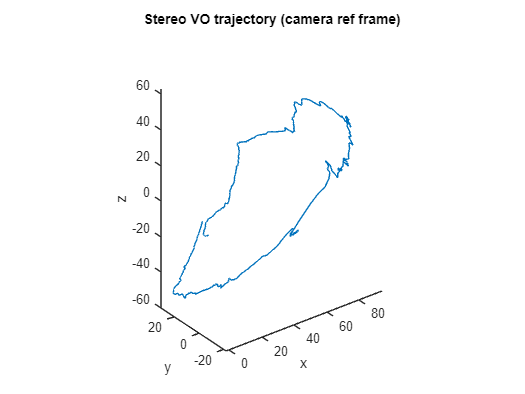

figure

plot3(t_hist(:,1),t_hist(:,2),t_hist(:,3)) %t_hist(:,3))
axis equal
xlabel('x');ylabel('y');zlabel('z')
title('Stereo VO trajectory (camera ref frame)');

### Ground truth trajectory included in the dataset

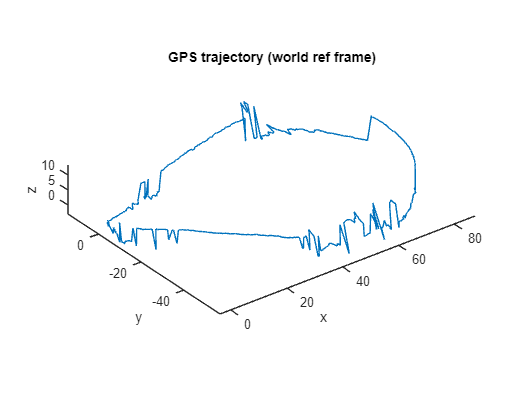

% Load GPS data
gpsData     = load('gpsLocation.mat');
gpsLocation = gpsData.gpsData.gpsLocation(1:step_frames:end,:);

figure
plot3(gpsLocation(:,1),gpsLocation(:,2),gpsLocation(:,3))%gpsLocation(:,3))
% plot3(gpsLocation(:,1),gpsLocation(:,2),)
axis equal
xlabel('x');ylabel('y');zlabel('z')
title('GPS trajectory (world ref frame)');

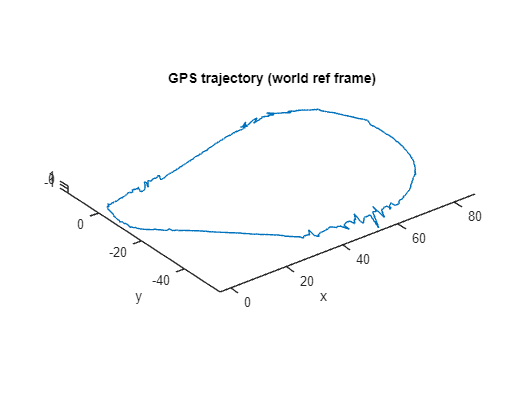

% Load GPS data
gpsData     = load('gpsLocation.mat');
gpsLocation = gpsData.gpsData.gpsLocation(1:step_frames:end,:);
gpsLocation_z0 = [gpsLocation(:,1),gpsLocation(:,2),zeros(size(gpsLocation(:,3)))];
gpsLocation_zmean = [gpsLocation(:,1),gpsLocation(:,2),mean(gpsLocation(:,3))*ones(size(gpsLocation(:,3)))];
figure
plot3(gpsLocation_z0(:,1),gpsLocation_z0(:,2),gpsLocation_z0(:,3))%gpsLocation(:,3))
% plot3(gpsLocation(:,1),gpsLocation(:,2),)
axis equal
xlabel('x');ylabel('y');zlabel('z')
title('GPS trajectory (world ref frame)');

## **Further to be done: **

***Align the two trajectories and then plot the two trajectories aligned. ***To do this, compute the transformation that best aligns the first 25% of the VO trajectory w.r.t. the GPS trajectory. Then apply that transformation to the complete VO trajectory. Note that the z coordinate of the GPS data may have outliers, and that we are only interested in visualizing the two trajectory on the ground plane.

rng(689);

% Determine the number of points for the first 25% of the trajectory
num_vo_points = round(0.25 *size(gpsLocation_z0, 1) );
num_gps_points = round(0.25 *size(gpsLocation_z0, 1));
% % Extract the first 25% of the VO and GPS trajectories
vo_25_percent = t_hist(1:num_vo_points, :); 
gps_25_percent_z0 = gpsLocation_z0(1:num_gps_points, :);
gps_25_percent_zmean = gpsLocation_zmean(1:num_gps_points, :);
% % Estimate the transformation that best aligns the two trajectories
estimatedTform_z0 = estimateGeometricTransform3D(gps_25_percent_z0,vo_25_percent,'rigid')';
estimatedTform_zmean = estimateGeometricTransform3D(gps_25_percent_zmean,vo_25_percent,'rigid')';
% gps_25_percent_z0 - gps_25_percent_zmean 
estimatedTform_z0.Rotation

ans =     0.2559    0.4039   -0.8783
   -0.9582    0.2262   -0.1751
    0.1279    0.8864    0.4449


estimatedTform_zmean.Rotation

ans =    -0.1997    0.2655   -0.9432
    0.6886    0.7229    0.0577
    0.6972   -0.6379   -0.3272


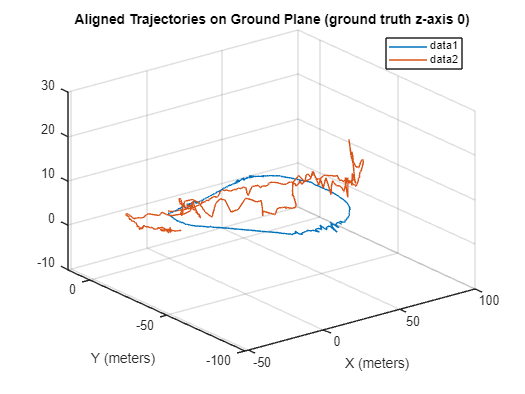

%Apply the transformation to the complete VO trajectory
aligned_vo_trajectory_z0 = (estimatedTform_z0.Rotation*t_hist')'; %+ estimatedTform_z0.Translation;
aligned_vo_trajectory_zmean = (estimatedTform_zmean.Rotation*t_hist')';
%+ estimatedTform_zmean.Translation;
%transformPointsForward(estimatedTform, t_hist);% Plot the aligned trajectories on the ground plane
% Plot the aligned trajectories on the ground plane
figure;
plot3(gpsLocation_z0(:, 1), gpsLocation_z0(:, 2), gpsLocation_z0(:, 3));%, 'g-', 'DisplayName', 'GPS Trajectory');
hold on;
plot3(aligned_vo_trajectory_z0(:, 1), aligned_vo_trajectory_z0(:, 2),aligned_vo_trajectory_z0(:, 3));%, 'b-', 'DisplayName', 'Aligned VO Trajectory');
hold off;

% Add labels, legend, and title
xlabel('X (meters)');
ylabel('Y (meters)');
title('Aligned Trajectories on Ground Plane (ground truth z-axis 0)');
legend('Location', 'best');
grid on;

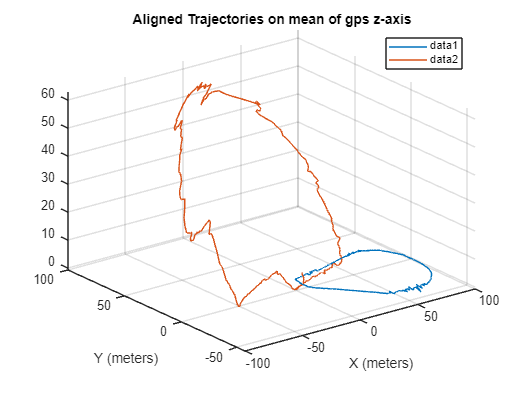

figure;
plot3(gpsLocation_zmean(:, 1), gpsLocation_zmean(:, 2), gpsLocation_zmean(:, 3));%, 'g-', 'DisplayName', 'GPS Trajectory');
hold on;
plot3(aligned_vo_trajectory_zmean(:, 1), aligned_vo_trajectory_zmean(:, 2),aligned_vo_trajectory_zmean(:, 3));%, 'b-', 'DisplayName', 'Aligned VO Trajectory');
hold off;

% Add labels, legend, and title
xlabel('X (meters)');
ylabel('Y (meters)');
title('Aligned Trajectories on mean of gps z-axis');
legend('Location', 'best');
grid on;

% Set the Z coordinate of the GPS trajectory to zero
gpsLocation(:, 3) = 0;

% Calculate the number of points for the first 25% of the trajectory
num_vo_points = size(t_hist, 1);
num_gps_points = size(gpsLocation, 1);
num_25_percent = round(0.25 * min(num_vo_points, num_gps_points));

% Extract the first 25% of the VO and GPS trajectories
vo_25_percent = t_hist(1:num_25_percent, :);
gps_25_percent = gpsLocation(1:num_25_percent, :);

% Use optimization to find the best transformation
% Define the error function for alignment
function [errors] = gpsTrajectoryError(transformation, gps_traj, vo_traj)
    % Build the transformation matrix
    T = zeros(4, 4);
    T(1:3, 1:3) = reshape(transformation(1:9), [3, 3]);
    T(1:3, 4) = transformation(10:12);
    T(4, 4) = 1;

    % Apply the transformation to the VO trajectory
    vo_traj_homo = [vo_traj, ones(size(vo_traj, 1), 1)]; % Homogeneous coordinates
    transformed_traj = (T * vo_traj_homo')';
    transformed_traj = transformed_traj(:, 1:3); % Extract transformed 3D points

    % Calculate errors for the first 25% of the trajectory
    errors = gps_traj - transformed_traj;
    errors = vecnorm(errors, 2, 2); % Euclidean distance
end

% Initial guess for transformation: Identity matrix + zero translation
initial_guess = [eye(3), zeros(3, 1)];
initial_guess = initial_guess(:); % Flatten into a vector

% Optimize the transformation using fminunc
options = optimoptions('fminunc', 'Algorithm', 'quasi-newton', 'Display', 'iter');
best_transformation = fminunc(@(x) sum(gpsTrajectoryError(x, gps_25_percent, vo_25_percent).^2), initial_guess, options);

                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0          13           170647                      1.83e+05
     1          26          7098.77    5.46465e-06       3.69e+04  
     2          39          179.899              1           30.8  
     3          91          171.478            820           30.1  
     4         104          153.611              1           13.9  
     5         143          153.424             91           47.5  
     6         156          151.745              1            297  
     7         169          149.705              1            421  
     8         182          147.864              1            317  
     9         195          147.294              1            105  
    10         208          147.231              1             11  
    11         221          147.229              1           2.05  
    12         234          147.229              

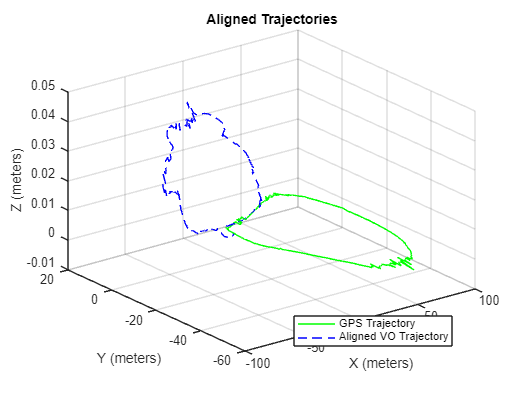


% Apply the optimized transformation to the complete VO trajectory
T_final = zeros(4, 4);
T_final(1:3, 1:3) = reshape(best_transformation(1:9), [3, 3]);
T_final(1:3, 4) = best_transformation(10:12);
T_final(4, 4) = 1;

t_hist_homo = [t_hist, ones(size(t_hist, 1), 1)]; % Homogeneous coordinates
aligned_vo_trajectory = (T_final * t_hist_homo')';
aligned_vo_trajectory = aligned_vo_trajectory(:, 1:3); % Extract aligned 3D points

% Plot the aligned trajectories
figure;
plot3(gpsLocation(:, 1), gpsLocation(:, 2), gpsLocation(:, 3), 'g-', 'DisplayName', 'GPS Trajectory');
% plot3(gpsLocation(:, 1), gpsLocation(:, 2), zeros(size(gpsLocation(:, 3))), 'g-', 'DisplayName', 'GPS Trajectory');
hold on;
plot3(aligned_vo_trajectory(:, 1), aligned_vo_trajectory(:, 2), aligned_vo_trajectory(:, 3), 'b--', 'DisplayName', 'Aligned VO Trajectory');
hold off;

% Add labels, legend, and title
xlabel('X (meters)');
ylabel('Y (meters)');
zlabel('Z (meters)');
title('Aligned Trajectories');
legend('Location', 'best');
grid on;

## **Supporting functions**

In Live scripts is possible to define functions that will run in your code. In this section, we can implement all the functions that we are going to use inside our code solution:

### Detect and extract features over all image

function [features,validPoints] = DetectandExtractFeatures(image,metricthreshold,levels,numPoints)
    gray_image  = im2gray(image);
    points = detectSURFFeatures(gray_image,'MetricThreshold',metricthreshold,'NumScaleLevels',levels);
    % Select a subset of features, uniformly distributed throughout the image
    points = selectUniform(points, numPoints, size(gray_image, 1:2));
    % Extract features
    [features, validPoints] = extractFeatures(gray_image, points);
end

### Bucketing

function [features,validPoints] = BucketFeaturesExtraction(image,metricthreshold,levels,numPoints,width_divs,height_divs)
   gray_image  = im2gray(image);
   [height,width] = size(gray_image);
   % Creating window are in where the features are extracted
   x = floor(linspace(1,width-width/width_divs,width_divs));
   y = floor(linspace(1,height-height/height_divs,height_divs));
   
   final_pts = [];
   for i = 1:length(y)
       for j = 1:length(x)
           % Region of interest
           roi = [x(j),y(i),floor(width/width_divs),floor(height/height_divs)];
           % Extracting features in roi
           points = detectSURFFeatures(gray_image,'MetricThreshold',metricthreshold,'NumScaleLevels',levels,'ROI',roi);
           final_pts = vertcat(final_pts,points.Location);
       end
   end
   final_pts = SURFPoints(final_pts);
   % Select a subset of features, uniformly distributed throughout the image
   %final_pts = selectUniform(final_pts, numPoints, size(gray_image, 1:2));
   % Extract Features
   [features, validPoints] = extractFeatures(gray_image, final_pts);
end

### Circular Matching function

function matched_pts_idxs = CircularMatching(pts_left1,pts_right1,pts_left2,pts_right2,desc_left1,desc_right1,desc_left2,desc_right2)
    % Iterate over all keypoint observations of image_left at t-1
    % A successful match is only declared when, after the cycle, the keypoint
    % in the left image at t-1 is tracked and match over all images.
    matches_l1 = [];
    matches_r1 = [];
    matches_l2 = [];
    matches_r2 = [];
    
    for kpt_left1 = 1:size(desc_left1,1)
        % Matching first feature in left t-1 with right t-1
        idx_pairs_l1_r1 = matchFeatures(desc_left1(kpt_left1,:),desc_right1);
        if isempty(idx_pairs_l1_r1)
            continue;
        end
    
        % Matching found feature in right t-1 with features in right t
        idx_pairs_r1_r2 = matchFeatures(desc_right1(idx_pairs_l1_r1(2),:),desc_right2);
        if isempty(idx_pairs_r1_r2)
            continue;
        end
    
        % Matching found feature in right t with features in left t
        idx_pairs_r2_l2 = matchFeatures(desc_right2(idx_pairs_r1_r2(2),:),desc_left2);
        if isempty(idx_pairs_r2_l2)
            continue;
        end
    
        % Matching found feature in left t with features in left t-1 closing the cycle
        idx_pairs_l2_l1 = matchFeatures(desc_left2(idx_pairs_r2_l2(2),:),desc_left1);
        if isempty(idx_pairs_l2_l1)
            continue;
        end
    
        % If the circular matching has been successful then accept the feature
        % as a match
        if (kpt_left1==idx_pairs_l2_l1(2))
            % Retrieve the coordinates of matched features
            matched_pt_l1 = pts_left1(kpt_left1);
            matched_pt_l2 = pts_left2(idx_pairs_r2_l2(2));
            matched_pt_r1 = pts_right1(idx_pairs_l1_r1(2));
            matched_pt_r2 = pts_right2(idx_pairs_r1_r2(2));
    
            % compute disparity
            disp1 = matched_pt_l1.Location(2) - matched_pt_r1.Location(2);
            disp2 = matched_pt_l2.Location(2) - matched_pt_r2.Location(2);
    
            % if disparities are positive then add the match
            %if (disp1 > 0 && disp2 >0)
                matches_l1 = [matches_l1;kpt_left1];
                matches_r1 = [matches_r1;idx_pairs_l1_r1(2)];
                matches_l2 = [matches_l2;idx_pairs_r2_l2(2)];
                matches_r2 = [matches_r2;idx_pairs_r1_r2(2)];
            %end
        end
    end
    matched_pts_idxs.left1 = matches_l1;
    matched_pts_idxs.right1 = matches_r1;
    matched_pts_idxs.left2 = matches_l2;
    matched_pts_idxs.right2 = matches_r2;
end

function [translationStack] = mvg_montecarlo_3d_to_3d_reg(pts_matches_l1,pts_matches_r1,pts_matches_l2,pts_matches_r2,stereoParams,noiseSTD,numRuns)
% function [resultStack] = mvg_montecarlo_3d_to_3d_reg(pts_matches_l1,pts_matches_r1,pts_matches_l2,pts_matches_r2,,numRuns,zmin, zmax)
%
% This function performs a Monte-Carlo runs using the method of 3D to 3D
% registration. Returns a stack with the translations for each run
 

% Initialize the stack
translationStack = zeros(numRuns,3);

for iterIdx = 1:numRuns

    % Add noise to the image points

%% your code here %%    
    pts_matches_l1 = pts_matches_l1 + (noiseSTD * randn(size(pts_matches_r1)));
    pts_matches_r1 = pts_matches_r1 + (noiseSTD * randn(size(pts_matches_r1)));
    pts_matches_l2 = pts_matches_l2 + (noiseSTD * randn(size(pts_matches_l2)));
    pts_matches_r2 = pts_matches_r2 + (noiseSTD * randn(size(pts_matches_r2)));
    
 
    % Triangulation of 3D points from pair 1

%% your code here %%    

    points3D_t1_noisy = triangulate(pts_matches_l1,pts_matches_r1,stereoParams);



    % Triangulation of 3D points from pair 2

%% your code here %%    

     points3D_t2_noisy = triangulate(pts_matches_l2,pts_matches_r2,stereoParams);



    % Select only points that are in a section of the 3D space

% uncomment these three lines after completing the rest %%            
    zmin = 0.5; % all points must be farther than this, in meters
    zmax = 50;  % all points must be closer than this, in meters
    [points3D_t1_noisy_valid,points3D_t2_noisy_valid] = select_based_on_z_distance(points3D_t1_noisy,points3D_t2_noisy,zmin,zmax);

    % Estimate the geometric transform

%% uncomment these two lines after completing the rest %%        
    [estimatedTform_noisy] = estimateGeometricTransform3D(points3D_t2_noisy_valid, points3D_t1_noisy_valid,'rigid','MaxDistance',10);
    translationStack(iterIdx,:) = estimatedTform_noisy.Translation;
end


end


function [translationStack] = mvg_montecarlo_2d_to_3d_reg(pts_matches_l1,pts_matches_r1,pts_matches_l2,pts_matches_r2,stereoParams,noiseSTD,numRuns)
% function [resultStack] = mvg_montecarlo_2d_to_3d_reg(pts_matches_l1,pts_matches_r1,pts_matches_l2,pts_matches_r2,noiseSTD,noiseSTD)
%
% This function performs a Monte-Carlo runs using the method of 2D to 3D
% registration. Returns a stack with the translations for each run



% Initialize the stack
translationStack = zeros(numRuns,3);

for iterIdx = 1:numRuns
    
    % Add noise to the image points

%% your code here %% 
    pts_matches_l1_noisy = pts_matches_l1 + (noiseSTD * randn(size(pts_matches_l1)));
    pts_matches_r1_noisy = pts_matches_r1 + (noiseSTD * randn(size(pts_matches_r1)));
    pts_matches_l2_noisy = pts_matches_l2 + (noiseSTD * randn(size(pts_matches_l2)));
    pts_matches_r2_noisy = pts_matches_r2 + (noiseSTD * randn(size(pts_matches_r2)));
    

    % Triangulation of 3D points from pair 1

%% your code here %% 

    
    points3D_t1_noisy = triangulate(pts_matches_l1_noisy,pts_matches_r1_noisy,stereoParams);
    % motion estimation

%% uncomment these two lines after completing the rest %%        
    intrinsics = stereoParams.CameraParameters1.Intrinsics;
    [~,t] = estimateWorldCameraPose(pts_matches_l2_noisy,points3D_t1_noisy,intrinsics,'MaxReprojectionError', 10);
    translationStack(iterIdx,:) = t;
end

   
end


function [points3D_t1_valid, points3D_t2_valid] = select_based_on_z_distance(points3D_t1, points3D_t2, zmin, zmax)
% Check points that are in a section of the 3D space 

%% your code here %%  
validMask = (points3D_t1(:,3) >= zmin) & (points3D_t1(:,3) <= zmax) & (points3D_t2(:,3) >= zmin) & (points3D_t2(:,3) <= zmax);
%validMask = find(zmin <= points3D_t1(:, 3) & points3D_t1(:, 3) <= zmax & zmin <= points3D_t2(:, 3) & points3D_t2(:, 3) <= zmax);

% Filter the points using the valid mask
points3D_t1_valid = points3D_t1(validMask, :);
points3D_t2_valid = points3D_t2(validMask, :);
end


function [inlierIdx] = getInliersIdx(pts_matches_l1,pts_matches_r1,pts_matches_l2,stereoParams)
% This is just a function to get inliers for our initial example for comparing methods

% Triangulation of 3D points at t-1
[points3D_t1,~,valid3D_t1] = triangulate(pts_matches_l1,pts_matches_r1,stereoParams);
points3D_t1 = points3D_t1(valid3D_t1,:);   

% motion estimation
intrinsics = stereoParams.CameraParameters1.Intrinsics;
[~,~,inlierIdx] = estimateWorldCameraPose(pts_matches_l2(valid3D_t1).Location,points3D_t1,intrinsics);
end

**Transform GPS**

function gTruth = helperTransformGPSLocations(gpsLocations, translation_trajectory, initial_Rot)

initialYawGPS  = atan( (gpsLocations(100, 2) - gpsLocations(1, 2)) / (gpsLocations(100, 1) - gpsLocations(1, 1)));
initialYawSLAM = atan((translation_trajectory(100,2) - ...
    translation_trajectory(1,2) / ...
    (translation_trajectory(100,1) - ...
    translation_trajectory(1,1))));

relYaw = initialYawGPS - initialYawSLAM;
relTranslation = translation_trajectory(1,1:3);

initialTform = rotationVectorToMatrix([0 0 relYaw]);
TRot = initial_Rot*initialTform';
for i = 1:size(gpsLocations, 1)
    gTruth(i, :) =  TRot * gpsLocations(i, :)' + relTranslation';
end
end